## Importing Images

clc; clear;

cd '..\MASK\batch_images' %Changing directory to picture folder
ds_left = imageDatastore('*_left.jpeg'); %Creating datastore of all images
original_images = cellfun(@imread, ds_left.Files, 'UniformOutput', false); %Converting all filenames (strings) to images (uint8)
labels = readtable('batch_labels.xls'); %Loading in ground truth labels for picture folder
left_images = cell(10,1); %Initializing cell array that will hold final segmented images

figure(1);
sgtitle('Importing Images')
hold on
for i = 1:10
    subplot(2,5,i);
    imshow(original_images{i});
end
hold off

## Preprocessing Channels

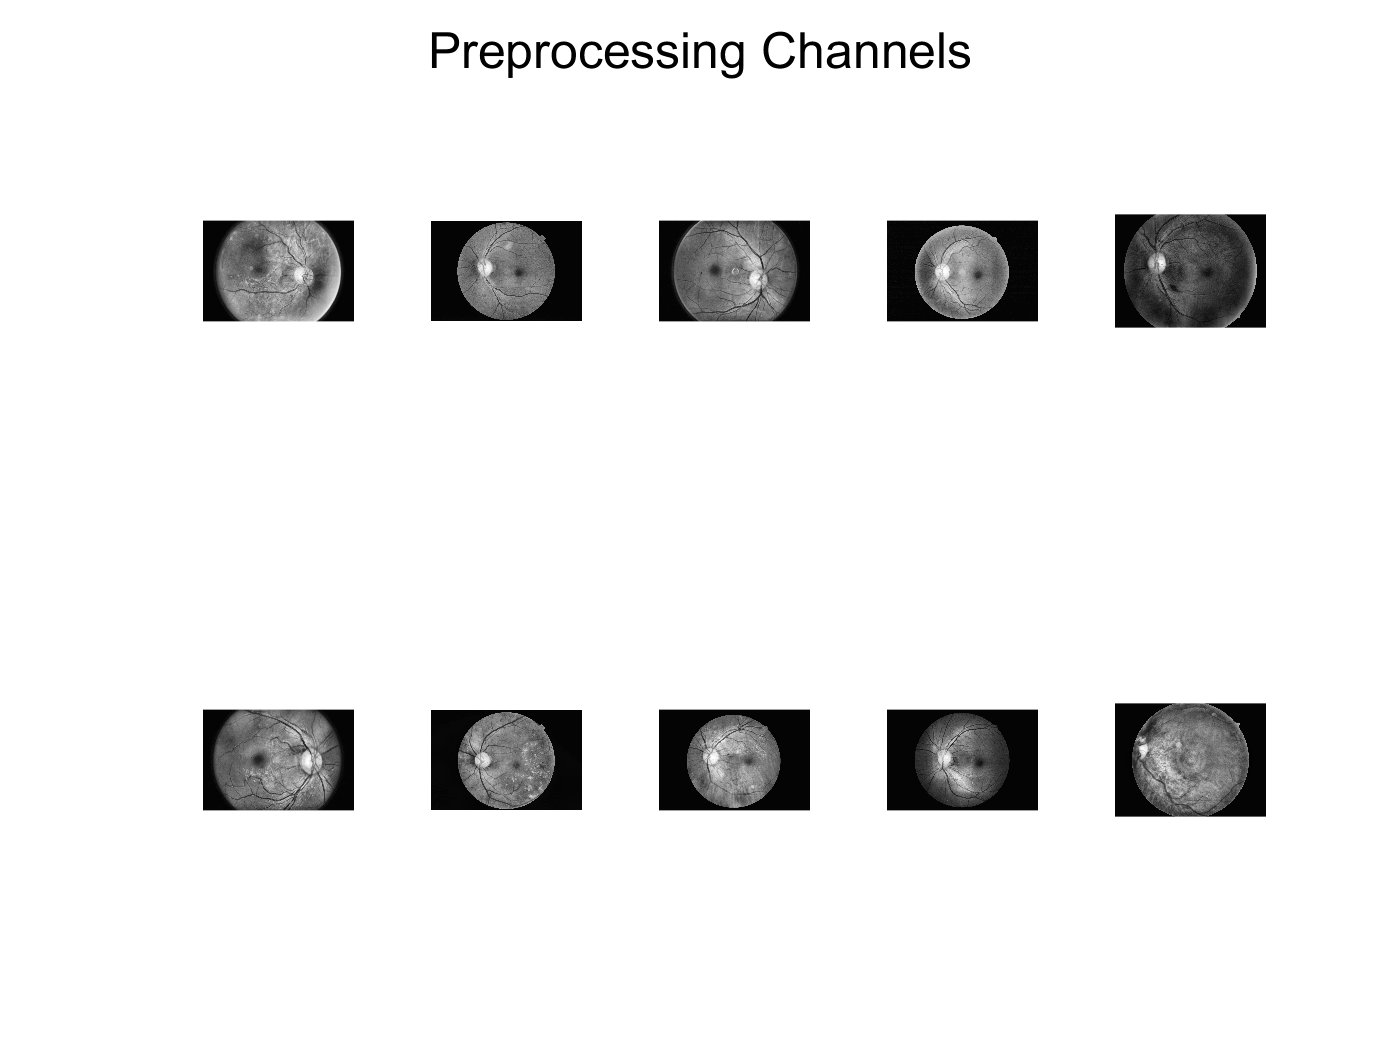

figure(2);
sgtitle('Preprocessing Channels')
hold on
for i = 1:10
    left_images{i} = im2gray(original_images{i}); %Converting rgb images to grayscale
    left_images{i} = adapthisteq(left_images{i}); %Using CLAHE to normalize contrast levels
    left_images{i} = medfilt2(left_images{i},[3 3]); %Applying a median filter to attenuate noise
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Eliminating Vessels

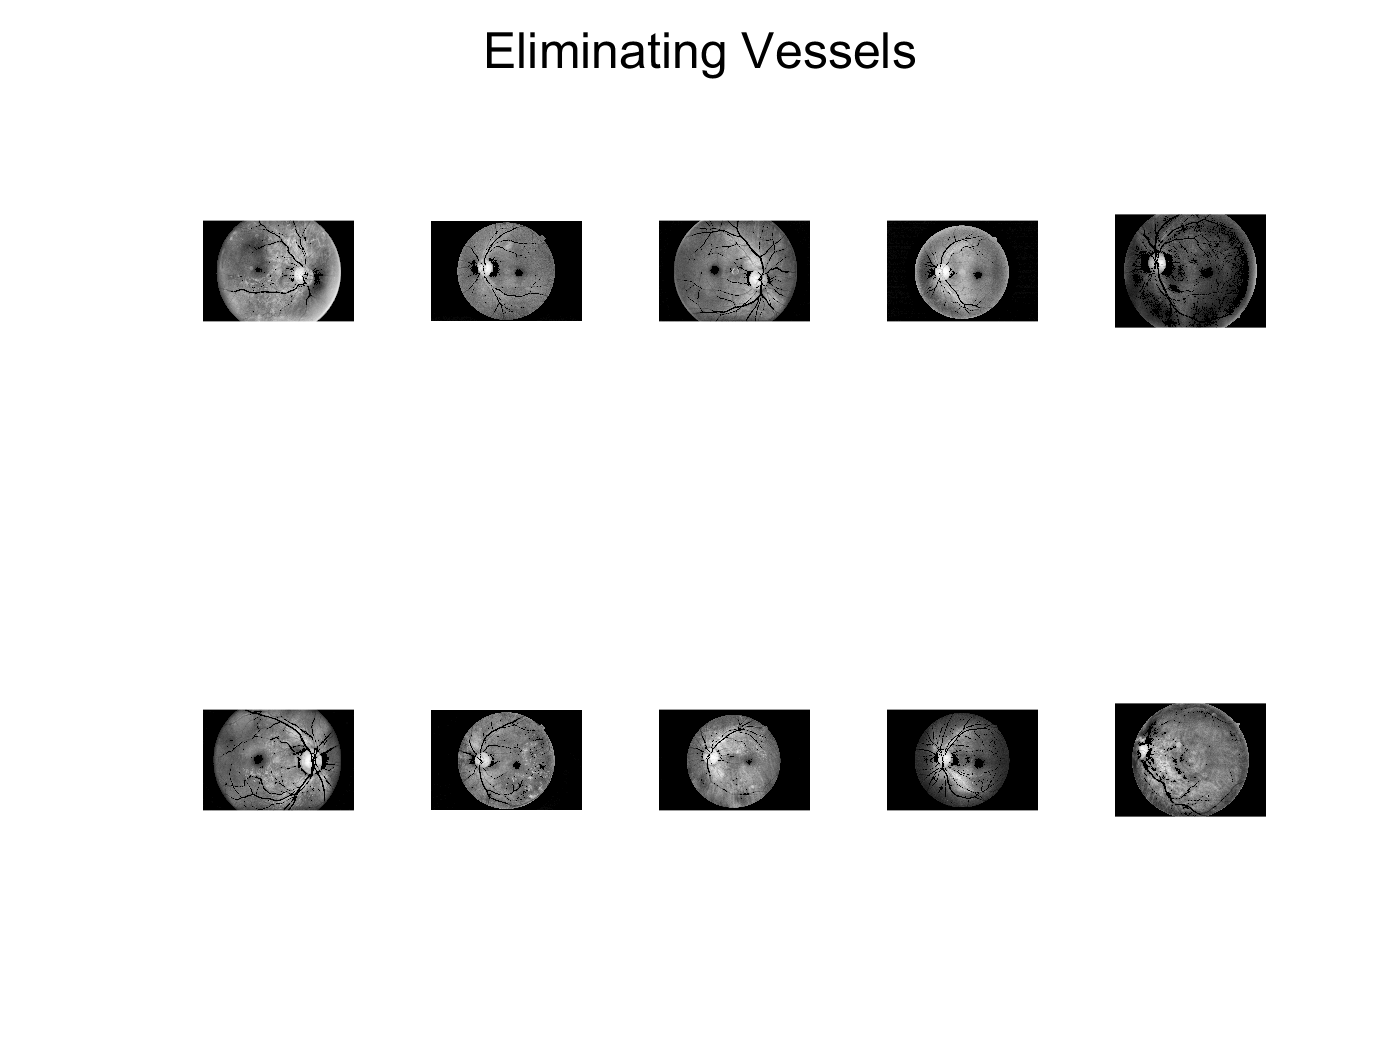

figure(3);
sgtitle('Eliminating Vessels');
hold on
for i = 1:10
    se = strel('line',3,90); %Create a line-shaped structuring element with a length of 3 at an angle of 90 degrees
    se2 = strel('line',3,0); %Create a line-shaped structuring element with a length of 3 at an angle of 0 degrees
    vessel = imdilate(original_images{i}(:,:,2),[se se2]); %Dilate the green channel with perpendicular line structuring element to detect vessel outlines
    se3 = strel('disk',1); %Create a disk-shaped structuring element with a radius of 1
    vessel = imerode(vessel,se3); %Erode the image with disk structuring elements to remove intermittent nearby patches
    vessel = imbinarize(vessel, "adaptive","ForegroundPolarity","bright","Sensitivity",0.7); %Create a binary mask of vessels
    left_images{i}(~vessel) = 0; %Remove vessels from original image
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Subtracting Optic Disks

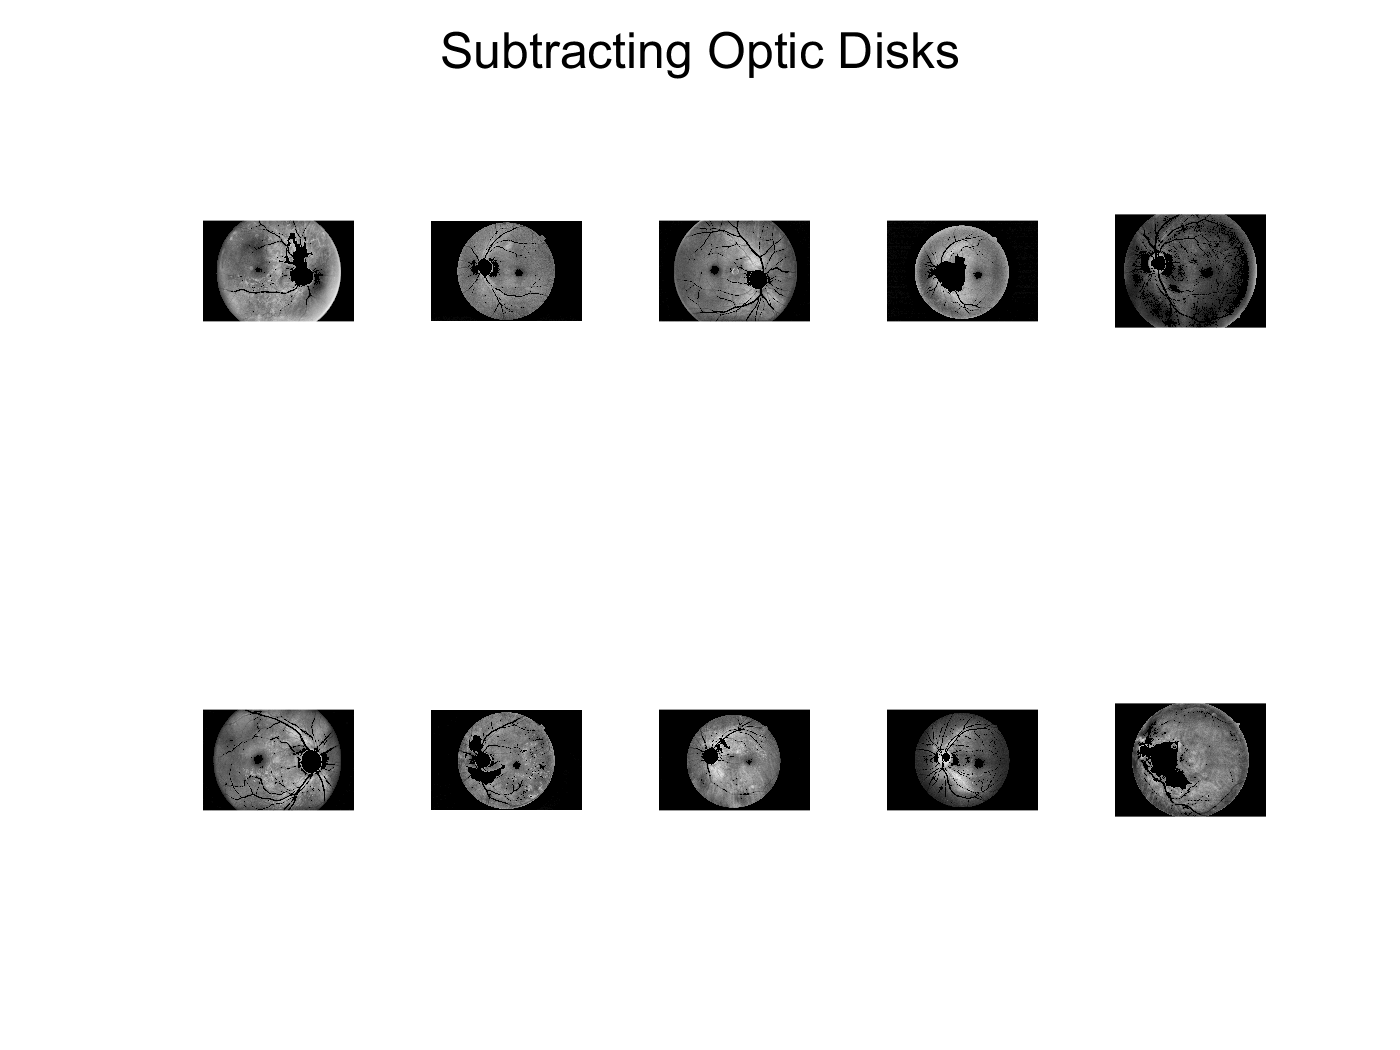

figure(4);
sgtitle('Subtracting Optic Disks');
hold on
for i = 1:10
    optic = original_images{i}(:,:,1) > 225; %Create a binary mask from the red channel to detect area of optic disk
    disk = strel('disk',50); %Create a disk-shaped structuring element with a radius of 50
    optic= imclose(optic,disk); %Conjoin the binary misk using the disk as a guide to obtain a final spherical shape
    left_images{i}(optic) = 0; %Subtract the optic disk from the original image
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Segmenting Exudates

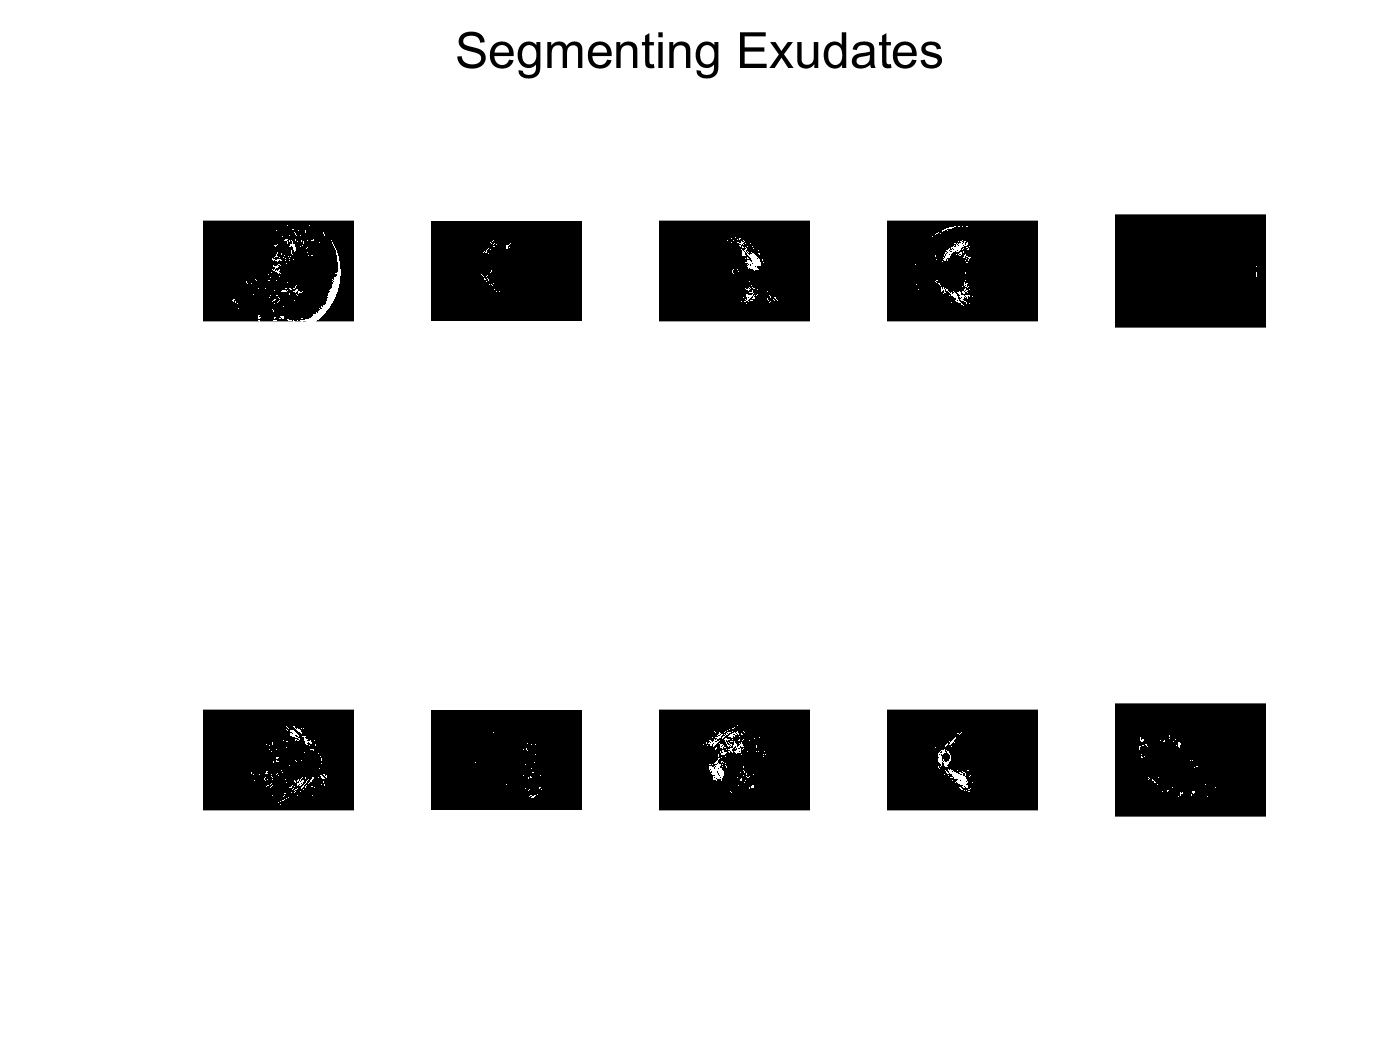

figure(5);
sgtitle('Segmenting Exudates');
hold on
for i = 1:10
    exudate = left_images{i} > 175; %Create a binary mask from the original image to detect areas of exudates
    left_images{i}(~exudate) = 0; %Remove all other pixels (background) other than exudates (foreground)
    left_images{i} = imbinarize(left_images{i}, "adaptive","ForegroundPolarity","bright","Sensitivity",0.7); %Create a binary image from detected exudates to homogenize intensities
    subplot(2,5,i);
    imshow(left_images{i});
    
end
hold off

## Classifying Severities

for i = 1:10
    pixels = sum(left_images{i}(:)); %Compute number of pixels comprising all detected exudate spots
        if pixels < 100000 %Classify level of severity based on number of thresholded pixels
            flag = 0;
        elseif pixels < 200000
            flag = 1;
        elseif pixels < 300000
            flag = 2;
        elseif pixels < 400000
            flag = 3;
        else
            flag = 4;
        end
        labels{i,3} = flag;
end

## Classifying Images

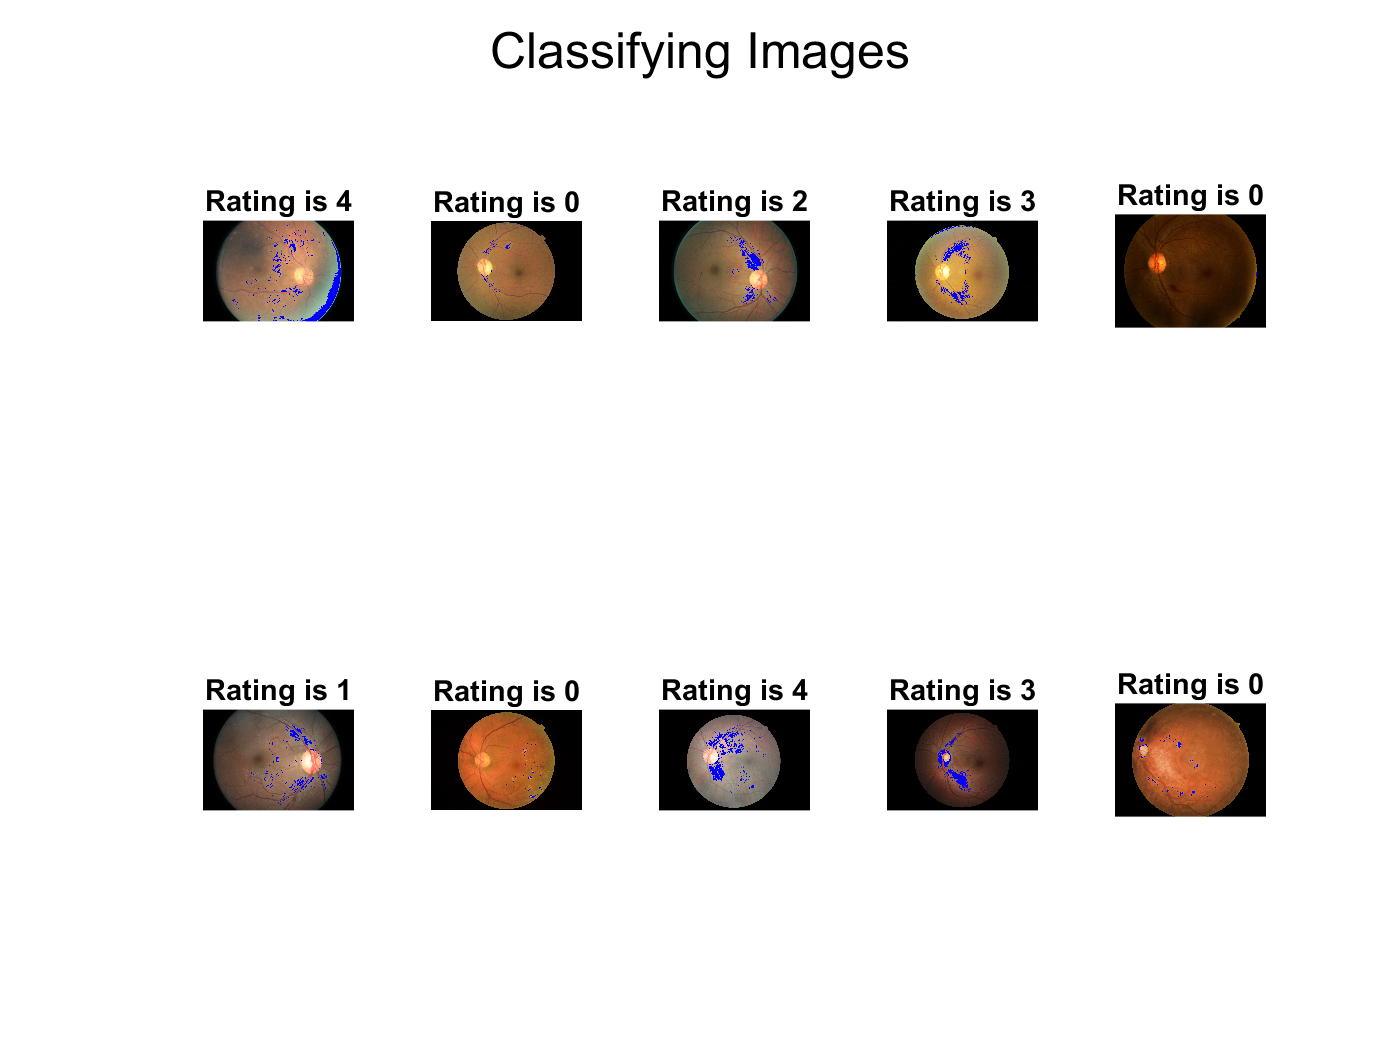

figure(6);
sgtitle('Classifying Images')
hold on
for i = 1:10
    subplot(2,5,i);
    imshow(imoverlay(original_images{i},left_images{i},'blue')); %Place exudate binary mask over original RGB image
    title(['Rating is ',num2str(labels{i,3})]);
end
hold off

## Analyzing Results

*This code would not run with the 'hold on' commands above, so we simply copy/paste it into the command window after running all the above sections.*

% cm = confusionchart(labels{:,1},labels{:,3});
% cm.Title = 'Confusion Matrix Chart of Clinician and Classifier Ratings'
% cm.YLabel = 'Clinician Rating'
% cm.XLabel = 'Classifier Rating'